# Binary classifier using classical apprach

clear;close all;clc;
label_array = char(label_array);

## Plotting datasets

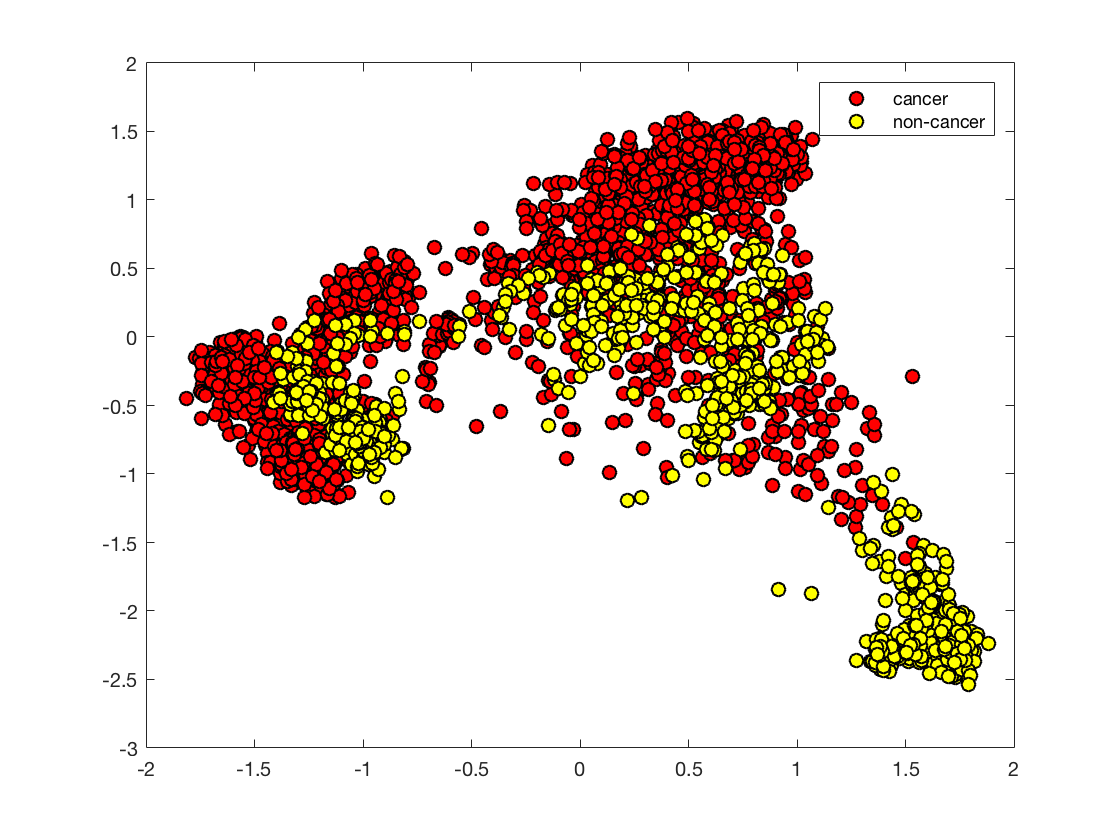


%2-D figure
pos = find(label_01 ==1);
neg = find(label_01 ==0);

plot(data_ninty(pos,1),data_ninty(pos,2),'ko','MarkerFaceColor','r','MarkerSize',7);
hold on ;
plot(data_ninty(neg,1),data_ninty(neg,2),'ko','MarkerFaceColor','y','MarkerSize',7);
legend('cancer','non-cancer');
hold off;

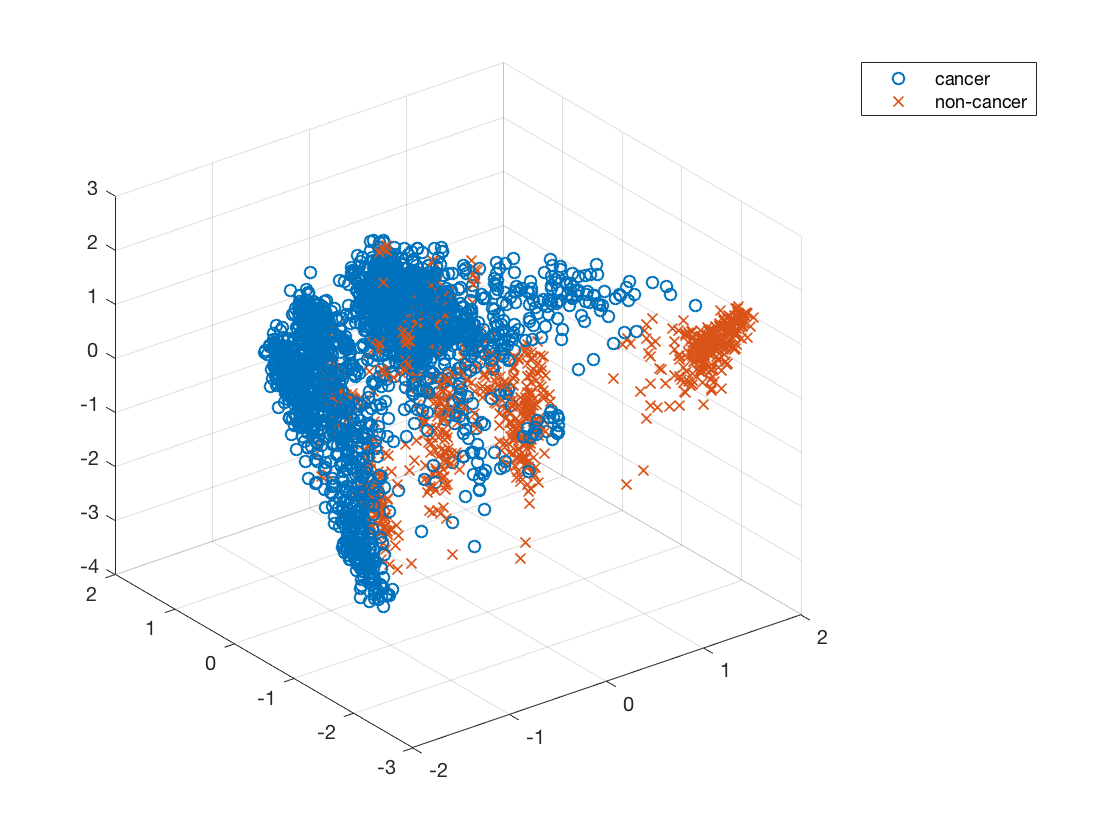


%3-D figure
figure
scatter3(data_ninty(pos,1),data_ninty(pos,2),data_ninty(pos,3),'o');
hold on 
scatter3(data_ninty(neg,1),data_ninty(neg,2),data_ninty(neg,3),'x');
legend('cancer','non-cancer');
hold off;

%Initializing the X(training set and Y)
X = final_data(:,1:441);
Y = label_01; % binary classification


% KNN
a = 2890;   %80percent training set
b = 3613-2890;


X = final_data(:,1:441);
random_x = X(randperm(size(X, 1)), :)
Y = label_array;


mdl = fitcknn(X, Y,'NumNeighbors',1,'Distance','cityblock');

cvmdl = crossval(mdl);
cvmdlloss = kfoldLoss(cvmdl);

% SVM
SVMmodel1 = fitcsvm(X,Y,'KernelFunction','linear');

random_x =    -1.3177   -0.5423    0.6159    1.4220   -0.0491    0.5457   -2.3679   -0.8106    0.6388   -0.9788   -0.5672    0.3735    1.5407    1.1736   -0.5294    0.9541   -1.2443    0.2835    1.3674   -0.3283   -0.7349    1.5792   -1.0613    0.2759   -0.2673    0.9330   -0.0847    1.2182    0.5696   -1.0082   -0.6209   -0.3033   -0.2603   -0.6844    0.2714    0.2738    1.2970   -0.1567    1.9511   -1.2222    1.8745   -0.8823   -0.7723   -0.9169    0.8010    0.0122    0.5504   -0.3977   -0.8542   -0.1592
    0.5033    1.0647   -0.0576   -0.0159   -0.0981   -0.6317   -0.0516    1.4230    0.3392   -0.8444    2.1891   -1.1945    2.3718    2.5038    0.3414   -1.2939    1.7631   -0.3208   -0.5295   -0.4367    2.2318    0.0260   -1.2612   -1.8192   -1.4615    0.2350    0.0265    0.3520    1.9881   -0.8419    1.8450   -0.9850   -0.7170   -0.7376    0.4752    1.9294    0.0035   -0.6977    0.3624    1.1697   -1.4105   -2.4548    0.9435   -2.6979   -0.5784   -0.6217    1.3894    0.9971   -0.88

CVSVMModel1 = crossval(SVMmodel1);
classLoss1 = kfoldLoss(CVSVMModel1);

SVMmodel2 = fitcsvm(X,Y,'KernelFunction','gaussian');
CVSVMModel2 = crossval(SVMmodel2);
classLoss2 = kfoldLoss(CVSVMModel2);

SVMmodel3 = fitcsvm(X,Y,'KernelFunction','polynomial');
CVSVMModel3 = crossval(SVMmodel3);
classLoss3 = kfoldLoss(CVSVMModel3);

c = categorical({'linear','gaussian','polynomial'});
bary = [classLoss1,classLoss2,classLoss3];
bar(c,bary);


% Logistic Regression


% Decision Tree
Mdl = fitctree(X,Y);
cvModl = crossval(Mdl);
classloss_tree = kfoldLoss(cvModl);